# Create Weather Prediction Model in MATLAB - Work

Create a predictive model to forecast the weather based on multiple technical indicators.  First starting with a smaller dataset to narrow down the choice of models, then once a model is selected scale up to train against larger datasets.

## Load In Data 

load("WeatherData_Small.mat", "WeatherData_Small")
head(WeatherData_Small)

Visualize the data (use the Plots Tab to explore visualizations)

%% Copy code here
stackedplot(WeatherData_Small);

The data provided is from multiple cities, lets pick a city

city = categories(WeatherData_Small.City)

Convert the city to string array to use the drop down task.

City = string(city);

Decide which city you want your data to come from

W_City = WeatherData_Small(WeatherData_Small.City == City(4), :);
W_City = removevars(W_City, "City");

Weather forecasts are only provided every 3 hours. We want to retime to have data interpolated every single hour. This would also give us more data to work with. Go to the Task button on the Live Editor tab. Select 'Retime Timetable' from all options as shown below.

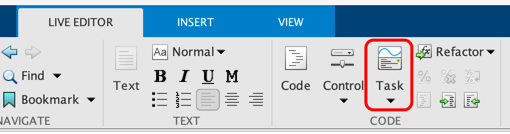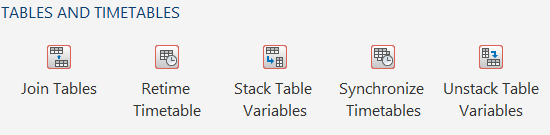

First, convert the table to timetable 

TT_City = table2timetable(W_City);

%% Write code here

% Retime timetable
newTimetable = retime(TT_City,"regular","linear","TimeStep",hours(1))


## Create Testing & Training Data Sets

Break the data into a training dataset for model building, and a testing dataset to assess model performance. We are using 10% of the data as testing data.

tempvar = floor(0.1 .* height(TT_City));
trainingData = timetable2table(TT_City(1:end-tempvar,1:5)); 
testingData = timetable2table(TT_City(end-tempvar+1:end,1:5));

## Use The [Regression Learner App](matlab:regressionLearner) With Training Data Set

## 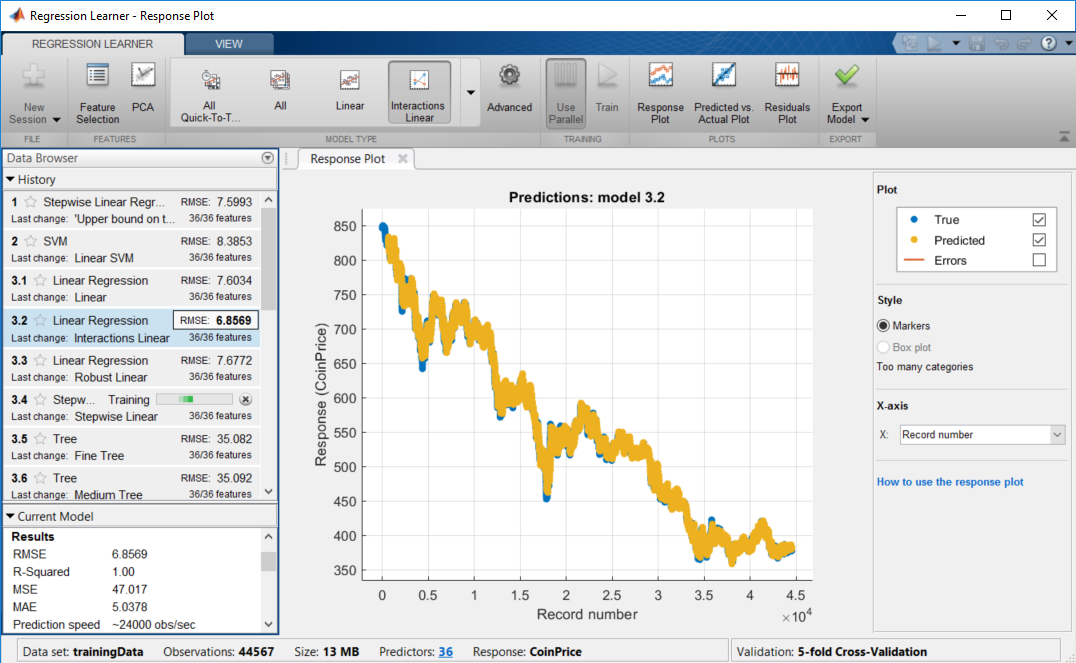

% Use Apps tab or enter code here




## Save Trained Model For Deployment

Save this trained machine learning model into a .mat file to be used with the prediction function as part of the Python web application.

% save('WeatherPredModel.mat', 'trainedModel');

load("WeatherPredModel.mat")
predictedTemp = trainedModel.predictFcn(testingData);

Date = testingData.DateLocal;
historicalData = testingData.T;

% create a table and visualize the comparison 
resultsTable = timetable(Date, historicalData, predictedTemp)

visualizeResults(resultsTable)
rmse = sqrt(mean(historicalData - predictedTemp, 'omitnan').^2)


**Helper function**

function visualizeResults(resultsTable)

% autogenerated code from creating a Plot with a timetable:
plot(resultsTable.Date, resultsTable.historicalData, 'DisplayName','historical Temperature','Marker','o');
hold on
plot(resultsTable.Date,resultsTable.predictedTemp,'DisplayName','predicted Temperature','Marker','*');
hold off

% customized code
legend
xlabel('Date')
ylabel('Temperature \circ F')
title('Out-Of-Sample Prediction')
end

*Copyright 2022 - 2023 The MathWorks, Inc.*